#  2  Επιλεκτική Cholesky

## **Eρώτηση 1**

Για διανύσματα u,d $\in \mathcal{R}^n$ με τα στοιχεία του d θετικά ο πίνακας D είναι της μορφής = diag(d) = $\left\lbrack \begin{array}{cccccc}
d_{11}  & 0 & 0 & 0 & \ldotp \ldotp  & 0\\
0 & d_{22}  & \ldotp \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & 0\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & d_{33}  & \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
0 & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & 0\\
\ldotp \ldotp  & 0 & \ldotp \ldotp  & 0 & 0 & d_{\textrm{nn}} 
\end{array}\right\rbrack$ και ο πίνακας ${\textrm{uu}}^T$= $\left\lbrack \begin{array}{c}
u_{11} \\
u_{12} \\
u_{13} \\
\ldotp \ldotp \\
\ldotp \ldotp \\
\ldotp \ldotp \\
u_{1n} 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{ccccccc}
u_{11}  & u_{12}  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  &  & u_{1n} 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{ccccccc}
{u^2 }_{11}  & {u_{11} u_{12} }  & u_{11} u_{13}  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & u_{11} u_{1n} \\
u_{11} u_{12}  & {u^2 }_{22}  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
u_{11} u_{13}  & \ldotp \ldotp \ldotp  & {u^2 }_{33}  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \\
\ldotp \ldotp \ldotp  &  &  &  &  &  & \\
 &  &  &  &  &  & \\
 &  &  &  &  &  & \\
 &  &  &  &  &  & {u^2 }_{\textrm{nn}} 
\end{array}\right\rbrack$ αρα, ο πίνακας $D +uu^T$ = $\left\lbrack \begin{array}{ccccccc}
{u^2 }_{11} +{d^2 }_{11}  & {u_{11} u_{12} }  & u_{11} u_{13}  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & u_{11} u_{1n} \\
u_{11} u_{12}  & {u^2 }_{22} +d_{22}^2  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
u_{11} u_{13}  & \ldotp \ldotp \ldotp  & {u^2 }_{33} +d_{33}^2  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \\
\ldotp \ldotp \ldotp  &  &  &  &  &  & \\
 &  &  &  &  &  & \\
 &  &  &  &  &  & \\
 &  &  &  &  &  & {u^2 }_{\textrm{nn}} +d_{\textrm{nn}}^2 
\end{array}\right\rbrack$ είναι συμμετρικός, είναι αυστήρα διαγώνια κυρίαρχος και έχει θετικά διαγώνια στοιχεία. Αρα είναι συμμετρικά θετικά ορισμένος.

## **Ερώτηση 2**

Για την επιλεκτική και άμεση επίλυση της Cholesky χρησιμοποιούμε τις παρακάτω σχέσεις

Τα διαγώνια στοιχεία 


$$L(i,i) = \sqrt{A(i,i) - \sum_{k=1}^{i-1} L(i,k)^2}$$


Τα υποδιαγώνια 


$$L(i,j) = \frac{A(i,j) - \sum_{k=1}^{j-1} L(i,k)L(j,k)}{L(j,j)}$$


% Πίνακες
n = 5; 
u = randi([-5, 5], n, 1); % Τυχαίο διάνυσμα u
d = randi([1, 10], n, 1); % Θετικό διάνυσμα d
j = 2; % Δείκτης !! Αλλαγή 

[lambda_jj, lambda_jj_minus1] = cholJ_236182(u, d, j);

% --- Αποτελέσματα ---
disp(['λ(j,j) = ', num2str(lambda_jj)]);

Λ(j,j) = 3.5


disp(['λ(j,j-1) = ', num2str(lambda_jj_minus1)]);

Λ(j,j-1) = 2.5981


Παράδειγμα για έλεγχο

A = diag(d)+u*u';
chol(A,"lower");


## **Ερώτηση 3**

n = 5; % Διάσταση
u = randi([-5, 5], n, 1); % Τυχαίο διάνυσμα u
d = randi([1, 10], n, 1); % Θετικό διάνυσμα d
j = 3;% αλλαγή για δοκιμή!!

% Υπολογισμός
[lambda_jj, lambda_jj_minus1] = cholJ_2361822(u, d, j);

% Εμφάνιση αποτελεσμάτων
disp(['λ(j,j) = ', num2str(lambda_jj)]);

Λ(j,j) = 2.6458


disp(['λ(j,j-1) = ', num2str(lambda_jj_minus1)]);

Λ(j,j-1) = 0


Παράδειγμα για έλεγχο 

A = diag(d)+u*u'

A =     10     0     6     0     9
     0     2     0     0     0
     6     0     7     0     6
     0     0     0     4     0
     9     0     6     0    10


chol(A,"lower")

ans =     3.1623         0         0         0         0
         0    1.4142         0         0         0
    1.8974         0    1.8439         0         0
         0         0         0    2.0000         0
    2.8460         0    0.3254         0    1.3394


**ΣΧΟΛΙΑΣΜΟΣ ΑΠΟΤΕΛΕΣΜΑΤΩΝ **

Παρατηρούμε ότι η επιλεκτρική Cholesky μας δίνει τα ίδια αποτελέσματα με την εντολή chol. Παρακάτω γίνεται και ανάλυση της διαφοράς μεταξύ των τιμών. 

## **Ερώτηση 4**

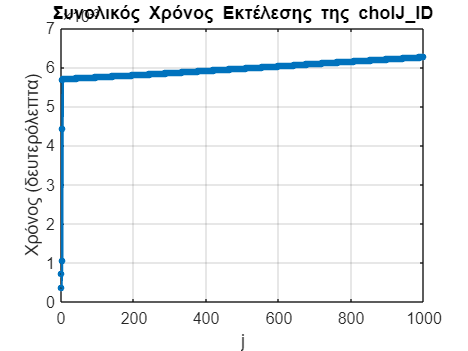

rng(236182);
n = 1000; 
d = rand(n, 1);
u = randn(n, 1); 

% Χρονομέτρηση
times = zeros(n, 1); % Πίνακας για αποθήκευση των χρόνων
for j = 1:n
    tic; % Έναρξη χρονομέτρησης
    [~, ~] = cholJ_236182(u, d, j); 
    times(j) = toc; % Καταγραφή χρόνου
end



totaltime = cumsum(times); % Υπολογισμός συσσωρευτικού χρόνου
figure;
plot(1:n, totaltime, '-o', 'LineWidth', 2, 'MarkerSize', 3);
xlabel('j');
ylabel('Χρόνος (δευτερόλεπτα)');
title('Συνολικός Χρόνος Εκτέλεσης της cholJ\_236182');
grid on;
set(gca, 'FontSize', 12);

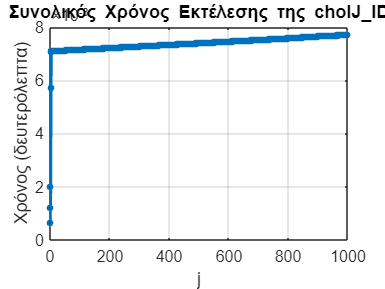

## **Σχολιασμός Γραφήματος **

Παρατηρούμε οτι ο χρόνος εκτέλεσης αυξάνει γραμμικά με μικρή κλίση καθώς αυξάνονται οι διαστάσεις του πίνακα 

## **Ερώτηση 5**

n = 1000;
u = randn(n, 1); % 
d = rand(n, 1) + 10;
[L_diag, L_subdiag] = cholALL_236182(u, d);
disp('Διαγώνια Στοιχεία L:');

Διαγώνια Στοιχεία L:


disp(L_diag);

    3.3350
    3.3055
    3.1637
    3.2668
    3.2132
    3.3856
    3.3272
    3.4120
    3.3871
    3.3150
    3.3515
    3.3014
    3.2710
    3.2797
    3.1818
    3.5493
    3.3722
    3.2513
    3.3594
    3.2994
    3.2584
    3.3570
    3.3439
    3.3003
    3.8214
    3.4662
    3.2400
    3.2144
    3.2762
    3.2443
    3.2893
    3.2258
    3.3240
    3.2820
    3.2527
    3.9348
    3.3197
    3.3476
    3.3580
    3.5522
    3.4124
    3.2438
    3.2578
    3.2087
    3.2751
    3.7560
    3.2674
    3.3146
    3.2332
    3.2463
    3.2341
    3.4358
    3.2911
    3.4984
    3.3355
    3.2098
    3.2034
    3.2504
    3.4267
    3.2942
    3.1845
    3.2954
    3.3958
    3.3068
    3.5267
    3.2151
    3.3193
    3.2775
    3.5833
    3.3536
    3.2476
    3.3052
    3.4247
    3.2300
    3.3733
    3.2268
    3.1992
    3.1912
    3.6481
    3.2687
    3.2897
    3.4014
    3.3683
    3.9634
    3.3831
    3.6356
    3.4338
    3.5941
    3.3732
    3.2393
    3.6399

disp('Υποδιαγώνια Στοιχεία L:');

Υποδιαγώνια Στοιχεία L:


disp(L_subdiag);

    0.2029
    0.0013
    0.0010
    0.0194
    0.0340
    0.2846
    0.3087
    0.3279
    0.1026
    0.0561
    0.1476
    0.1430
    0.1015
   -0.0204
   -0.0454
    0.4444
   -0.2006
   -0.2030
   -0.1120
    0.0319
    0.0619
   -0.1142
   -0.1312
   -0.4768
   -0.6951
    0.2746
   -0.0959
   -0.0967
    0.0334
   -0.0087
    0.0095
   -0.0277
   -0.0988
   -0.0856
    0.3089
   -0.2797
    0.1268
    0.2329
   -0.3845
   -0.4483
   -0.2480
   -0.1354
    0.0837
   -0.0558
    0.2291
   -0.1331
   -0.0200
   -0.0475
    0.1006
    0.0810
   -0.1618
   -0.1154
    0.1383
   -0.3211
   -0.0761
   -0.0367
   -0.0913
    0.1947
   -0.1600
   -0.0157
   -0.0180
    0.2262
    0.0413
    0.0524
    0.1769
   -0.1211
   -0.1587
   -0.2636
    0.4335
    0.0446
   -0.0113
   -0.0868
   -0.1199
    0.0876
   -0.0734
    0.0070
   -0.0022
   -0.0520
   -0.1978
    0.0836
    0.1699
    0.2127
    0.5760
   -0.4950
   -0.4215
   -0.4961
    0.4981
    0.3215
   -0.1431
    0.3203
    0.1707

Ελεγχος Αποτελεσμάτων 

A = diag(d)+u*u';
chol(A,"lower")

ans =     3.3350         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2029    3.3055         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

## **Ερώτηση 6**

n_values = [100, 500, 1000, 2000]; % Διαφορετικές διαστάσεις πίνακα
times_236182 = zeros(size(n_values)); % Χρόνοι cholJ_236182
times_2361822 = zeros(size(n_values)); % Χρόνοι cholJ_2361822
times_ALL_236182 = zeros(size(n_values)); % Χρόνοι cholALL_236182

for idx = 1:length(n_values)
    n = n_values(idx);
    u = randn(n, 1); % Τυχαίο διάνυσμα u
    d = rand(n, 1); % Θετικό διάνυσμα d
    tic;
    for j = 1:n
        [~, ~] = cholJ_236182(u, d, j); 
    end
    times_236182(idx) = toc;-
    tic;
    for j = 1:n
        [~, ~] = cholJ_2361822(u, d, j);
    end
    times_2361822(idx) = toc;
    tic;
    [~, ~] = cholALL_236182(u, d);
    times_ALL_236182(idx) = toc;
end

disp('Χρόνοι Εκτέλεσης:');

Χρόνοι Εκτέλεσης:


disp(table(n_values', times_236182', times_2361822', times_ALL_236182', ...
    'VariableNames', {'n', 'cholJ_236182_time', 'cholJ_2361822_time', 'cholALL_ID_time'}));

     n      cholJ_236182_time    cholJ_2361822_time    cholALL_ID_time
    ____    _________________    __________________    _______________

     100          0.00199            0.0060479            0.0064919   
     500        0.0002405            0.0006823            0.0008023   
    1000        0.0013984             0.000841            0.0011238   
    2000        0.0010602            0.0006251            0.0037436   



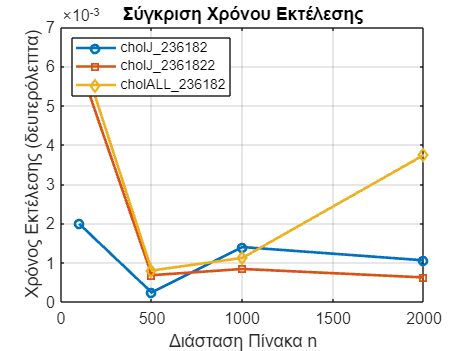


figure;
plot(n_values, times_236182, '-o', 'LineWidth', 2, 'DisplayName', 'cholJ\_236182');
hold on;
plot(n_values, times_2361822, '-s', 'LineWidth', 2, 'DisplayName', 'cholJ\_2361822');
plot(n_values, times_ALL_236182, '-d', 'LineWidth', 2, 'DisplayName', 'cholALL\_236182');
hold off;
xlabel('Διάσταση Πίνακα n');
ylabel('Χρόνος Εκτέλεσης (δευτερόλεπτα)');
title('Σύγκριση Χρόνου Εκτέλεσης');
legend('show', 'Location', 'northwest');
grid on;
set(gca, 'FontSize', 12);

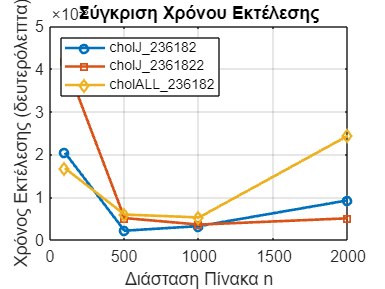

## Σχολιασμός Αποτελεσμάτων 

Τα αποτελέσματα δεν ειναι σωστά. Το γράφημα δείχνει οτι ο χρόνος μειώνεται καθώς αυξάνεται το μέγεθος του πίνακα. Κάποιο λάθος έχει γίνει στον κώδικα που δεν μπορώ να εντωπίσω 

## Ερώτηση 7

rng(236182); 
n = 1000; % Διάσταση του πίνακα
u = randn(n, 1); % Τυχαίο διάνυσμα u
d = rand(n, 1) + 10; % Θετικό διάνυσμα d (προσθέτουμε 10 για σταθερότητα)
A = diag(d)+u*u';

[L_diag, L_subdiag] = cholALL_236182(u, d)

L_diag =     3.4960
    3.1728
    3.2945
    3.2598
    3.5525
    3.3913
    3.5674
    3.2626
    3.2601
    3.4778


L_subdiag =     0.0768
    0.0336
   -0.0059
    0.0165
   -0.3642
   -0.3946
    0.3911
   -0.1361
   -0.1864
   -0.3408


L_chol = chol(A, 'lower') % Κάτω τριγωνικός παράγοντας

L_chol =     3.4960         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0768    3.1728         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

L_chol_diag = diag(L_chol); % Διαγώνια στοιχεία
L_chol_subdiag = diag(L_chol, -1); % Υποδιαγώνια στοιχεία

max_diag_diff = max(abs(L_diag - L_chol_diag)); % max_j |λ(j,j) - L(j,j)|
max_subdiag_diff = max(abs(L_subdiag - L_chol_subdiag)); % max_j |λ(j,j-1) - L(j,j-1)|

% --- Έλεγχος Ορθότητας ---
if max_diag_diff > n*eps
    disp(['Η διαφορά στα διαγώνια στοιχεία είναι εκτός ανοχής: ', num2str(max_diag_diff)]);
else
    disp('Οι διαγώνιες τιμές είναι εντός της ανοχής.');
end

Η διαφορά στα διαγώνια στοιχεία είναι εκτός ανοχής: 1.1804



if max_subdiag_diff > n*eps
    disp(['Η διαφορά στα υποδιαγώνια στοιχεία είναι εκτός ανοχής: ', num2str(max_subdiag_diff)]);
else
    disp('Οι υποδιαγώνιες τιμές είναι εντός της ανοχής.');
end

Η διαφορά στα υποδιαγώνια στοιχεία είναι εκτός ανοχής: 1.2066



% --- Αποτελέσματα ---
disp(['Μέγιστη διαφορά στα διαγώνια στοιχεία: ', num2str(max_diag_diff)]);

Μέγιστη διαφορά στα διαγώνια στοιχεία: 1.1804


disp(['Μέγιστη διαφορά στα υποδιαγώνια στοιχεία: ', num2str(max_subdiag_diff)]);

Μέγιστη διαφορά στα υποδιαγώνια στοιχεία: 1.2066


## **ΑΣΚΗΣΗ 2 - ΕΡΩΤΗΣΗ 2 - ΣΥΝΑΡΤΗΣΗ 1**

function [lambda_jj, lambda_jj_minus1] = cholJ_236182(u, d, j)
    n = length(d);
    if j < 1 || j > n
        error('Ο δείκτης j πρέπει να είναι μεταξύ 1 και n.');
    end

    A_jj = d(j) + u(j)^2; 
    if j > 1
        A_jj_minus1 = u(j) * u(j-1); 
    else
        A_jj_minus1 = 0; 
    end

    if j == 1
        lambda_jj = sqrt(A_jj); % Υπολογισμός του πρώτου διαγώνιου στοιχείου
        lambda_jj_minus1 = 0; % Δεν υπάρχει προηγούμενη στήλη
    else
        lambda_jj_minus1 = A_jj_minus1 / sqrt(d(j-1) + u(j-1)^2); % Υποδιαγώνιο στοιχείο
        lambda_jj = sqrt(A_jj - lambda_jj_minus1^2); % Διαγώνιο στοιχείο
    end
end


## **ΑΣΚΗΣΗ 2 - ΕΡΩΤΗΣΗ 2  - ΣΥΝΑΡΤΗΣΗ 2**

function [lambda_jj, lambda_jj_minus1] = cholJ_2361822(u, d, j)
    if j < 1 || j > length(d)
        error('Ο δείκτης j πρέπει να είναι μεταξύ 1 και n.');
    end

    
    A_jj = d(j) + u(j)^2;

    if j == 1
        lambda_jj = sqrt(A_jj); % Υπολογισμός διαγώνιου στοιχείου
        lambda_jj_minus1 = 0;  % Δεν υπάρχει προηγούμενη στήλη
        return;
    end

    % Υπολογισμός του A(j,j-1)
    A_jj_minus1 = u(j) * u(j-1);

    % Υπολογισμός της ρίζας του προηγούμενου διαγώνιου στοιχείου
    prev_lambda = sqrt(d(j-1) + u(j-1)^2);

    % Υπολογισμός του υποδιαγώνιου στοιχείου L(j,j-1)
    lambda_jj_minus1 = A_jj_minus1 / prev_lambda;

    % Υπολογισμός του διαγώνιου στοιχείου L(j,j)
    lambda_jj = sqrt(A_jj - lambda_jj_minus1^2);
end

## **ΑΣΚΗΣΗ 2 - ΕΡΩΤΗΣΗ 2  - ΣΥΝΑΡΤΗΣΗ 2**

function [L_diag, L_subdiag] = cholALL_236182(u, d)
    n = length(d);
    if length(u) ~= n
        error('Τα διανύσματα u και d πρέπει να έχουν το ίδιο μήκος.');
    end
    % Αρχικοποίηση των διανυσμάτων εξόδου 
    L_diag = zeros(n, 1, 'like', u); 
    L_subdiag = zeros(n-1, 1, 'like', u);   
    L_diag = cast(L_diag, 'double');
    L_subdiag = cast(L_subdiag, 'double');
    u = cast(u, 'double');
    d = cast(d, 'double'); 
    for j = 1:n
        if j == 1
            % Υπολογισμός του πρώτου διαγώνιου στοιχείου με αποφυγή αριθμητικών σφαλμάτων
            L_diag(j) = sqrt(max(d(j) + u(j)^2, eps));
        else
            % Υπολογισμός της πρώτης υποδιαγωνίου 
            paranomastis = max(L_diag(j-1), eps);  % Αποφυγή διαίρεσης με πολύ μικρές τιμές
            L_subdiag(j-1) = (u(j) * u(j-1)) / paranomastis;

            % Υπολογισμός της κύριας διαγωνίου
            diag_term = d(j) + u(j)^2 - L_subdiag(j-1)^2;

            % Αν η τιμή γίνει αρνητική λόγω αριθμητικού σφάλματος, προσαρμόζουμε την τιμή
            if diag_term < 1e-12
                diag_term = max(diag_term, 1e-12); 
            end

            L_diag(j) = sqrt(diag_term);
        end
    end
end